# Download IAPR TC-12

dataDir = fullfile(tempdir,'iaprtc12');

if ~exist(dataDir,'dir')
    url = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
    fprintf('Downloading IAPR TC-12 data set (1.8 GB)...\n');
    try
        untar(url,dataDir);
    catch
        % On some Windows machines, the untar command throws an error for .tgz
        % files. Rename to .tg and try again.
        fileName = fullfile(tempdir,'iaprtc12.tg');
        websave(fileName,url);
        untar(fileName,dataDir);
    end
    fprintf('Done.\n\n');
end

# Generator

% net G
inputsize = [64 64 3] ;
ks = 3 ; % kernel size
nf = 64 ; % num filters
layerG = [
    imageInputLayer(inputsize,"Normalization","none","Name","in")
    convolution2dLayer(9,nf,"Stride",1,"Padding","same","Name","c1")
    preluLayer(nf, Name="pr1")
] ;
for i = 1:16
    layerG = [
        layerG

        convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","b"+string(i)+"c1")
        batchNormalizationLayer("Name","b"+string(i)+"b1")
        preluLayer(nf, Name="bpr"+string(i))
        convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","b"+string(i)+"c2")
        batchNormalizationLayer("Name","b"+string(i)+"b2")
        additionLayer(2,"Name","ba"+string(i))
    ];
end
layerG = [
    layerG

    convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","c2")
    batchNormalizationLayer("Name","b1")
    additionLayer(2,"Name","a")

    convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","c3")
%     PixelShuffleLayer(2,Name="ps1")
    depthToSpace2dLayer([2 2], 'Name', 'ps1', 'Mode', 'dcr');
    preluLayer(nf/4, Name="pr2")
    convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","c4")
%     PixelShuffleLayer(2,Name="ps2")
    depthToSpace2dLayer([2 2], 'Name', 'ps2', 'Mode', 'dcr');
    preluLayer(nf/4, Name="pr3")

    convolution2dLayer(9,3,"Stride",1,"Padding","same","Name","output")
];

layergraphG = layerGraph(layerG) ;
layergraphG = connectLayers(layergraphG,"pr1","ba1/in2") ;
layergraphG = connectLayers(layergraphG,"pr1","a/in2") ;
for i = 1:15
    layergraphG = connectLayers(layergraphG,"ba"+string(i),"ba"+string(i+1)+"/in2") ;
end

netG = dlnetwork(layergraphG) ;

# Discriminator

% net D
inputsize = [256 256 3] ;
ks = 3 ; % kernel size
nf = 64 ; % num filters
scale = 0.2 ; % leaky relu scale(alpha)
layerD = [
    imageInputLayer(inputsize,"Normalization","none","Name","in")
    convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","c1")
    leakyReluLayer(scale,"Name","lr1")
    convolution2dLayer(ks,nf,"Stride",1,"Padding","same","Name","c2")
    batchNormalizationLayer("Name","b1")
    leakyReluLayer(scale,"Name","lr2")
] ;

for i = 1:3
    layerD = [
        layerD 

        convolution2dLayer(ks,nf*(2^i) ,"Stride",1,"Padding","same","Name","b"+string(i)+"c1")
        batchNormalizationLayer("Name","b"+string(i)+"b1")
        leakyReluLayer(scale,"Name","b"+string(i)+"lr1")
        convolution2dLayer(ks,nf*(2^i) ,"Stride",2,"Padding","same","Name","b"+string(i)+"c2")
        batchNormalizationLayer("Name","b"+string(i)+"b2")
        leakyReluLayer(scale,"Name","b"+string(i)+"lr2")
    ] ;
end
layerD = [
    layerD

    fullyConnectedLayer(1024,"Name","fc1")
    leakyReluLayer(scale,"Name","lro")
    fullyConnectedLayer(1,"Name","fcout")
%     sigmoidLayer("Name","output")
] ;

layergraphD = layerGraph(layerD) ;
netD = dlnetwork(layergraphD) ;

# pre-trained Vgg network for contentloss

% Vgg19 for loss
vgg = vgg19 ; 
vgg = vgg.Layers ;
input = imageInputLayer([256 256 3],"Name","vggin","Normalization","none") ;
vgg(1) = input ;

% Higher level
Hvgg = dlnetwork( layerGraph( vgg(1:37) ) ) ;

%% Lower level
% Lvgg = dlnetwork( layerGraph( vgg(1:10) ) ) ;

# Detail parameters

% options
% maxEpoch = 200 ; 
startIteration = 1 ;
maxIteration = 4*10^5 ;
ResTrained = false ;
miniBatchSize = 16 ;
learningRateG = 1e-4 ; %10^-4
learningRateD = 1e-4 ;
% u = nan ;
% v = nan ;

trailingAvgG = [];
trailingAvgSqG= [];
trailingAvgD = [];
trailingAvgSqD = [];


# DataSet

% DataSet
% IAPR TC-12 Database
dataDir = fullfile(tempdir,'iaprtc12/iaprtc12');
imageDir = fullfile(dataDir,'images') ;
exts = {'.jpg','.bmp','.png'};
imds = imageDatastore(imageDir, ...
    'IncludeSubfolders',true,'FileExtensions',exts);
imds.ReadSize = 8 ;
imds = shuffle(imds) ;

# Figure setting

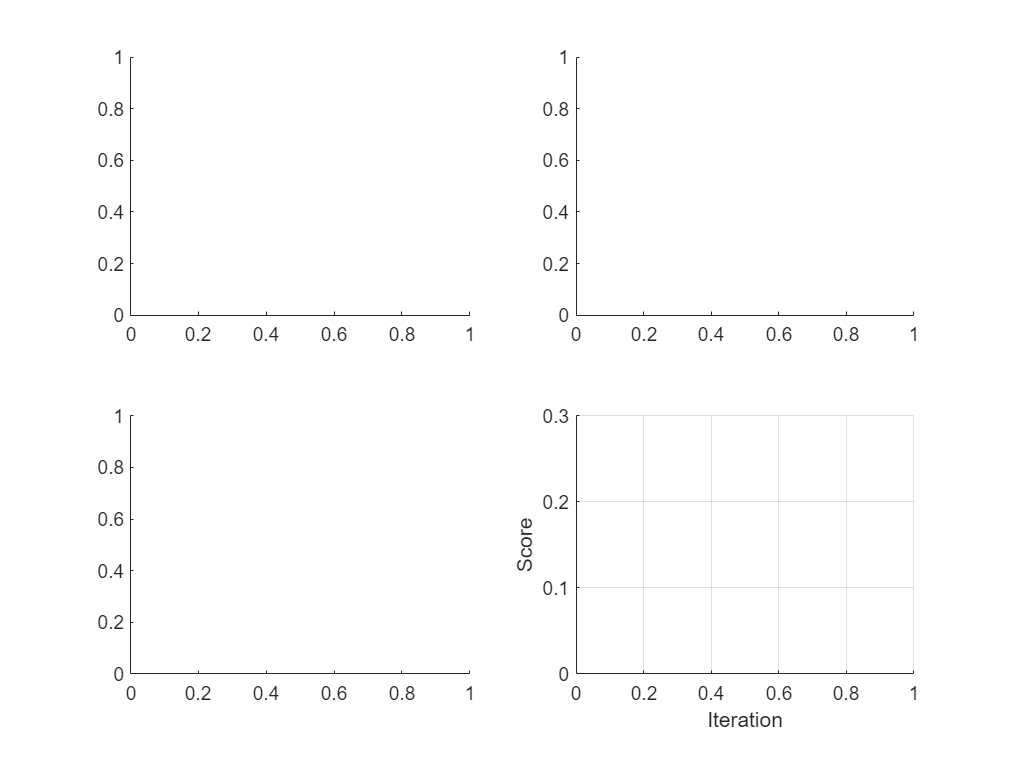

f = figure;
f.Position(3) = 2*f.Position(3);
f.Position(4) = 2*f.Position(4);
scoreAxes = subplot(2,2,1);
imageAxes1 = subplot(2,2,2);
imageAxes2 = subplot(2,2,3);
imageAxes3 = subplot(2,2,4);
lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);

ylim([0 0.3])
xlabel("Iteration")
ylabel("Score")
grid on

# Training

% training
if ResTrained == true
    startIteration = maxIteration/2 +1 ;
    ResNet = load("Models\SRResNet.mat") ;
    netG = ResNet.netG ;
end
start = tic;
for iteration = startIteration:maxIteration

    if ~(hasdata(imds))
        reset(imds)
        imds = shuffle(imds) ;
    end

    data = read(imds) ;
    [x,z] = dataPreprocess(data,16) ;
    
    % SN
%     [u,v,netD] = spectralNormalize(u,v,netD) ;

    if isnan(netG.Learnables.Value{1,1})
        fprintf("G nan") ;
        break
    end
    
    % SRGAN train after SRResNet train 2*10^5
    if iteration > maxIteration/2 

        [gradientsG, gradientsD, stateG, scoreG, scoreD, y] = dlfeval(@modelGradients, netG, netD, x, z,Hvgg);
        netG.State = stateG;
    
        % adam opt Discriminator
        [netD,trailingAvgD,trailingAvgSqD] = ...
            adamupdate(netD, gradientsD, trailingAvgD, trailingAvgSqD, iteration,learningRateD);
        % adam opt Generator
        [netG,trailingAvgG,trailingAvgSqG] = ...
            adamupdate(netG, gradientsG, trailingAvgG, trailingAvgSqG, iteration,learningRateG); 
    else
        [gradientsG, stateG, scoreG, y] = dlfeval(@ResmodelGradients, netG, x, z);
        netG.State = stateG;

        [netG,trailingAvgG,trailingAvgSqG] = ...
        adamupdate(netG, gradientsG, trailingAvgG, trailingAvgSqG, iteration,learningRateG);
    end


    % plot figure 
    if mod(iteration,100) == 0 || iteration == startIteration
        sr = rescale( extractdata( y(:,:,:,1) ) ) ;
        hr = rescale( extractdata( x(:,:,:,1) ) ) ;
        lr = rescale( extractdata( z(:,:,:,1) ) ) ;
        subplot(2,2,2);
        image(imageAxes1,sr)
        xticklabels([]);
        yticklabels([]);
        title("SR Images");
        subplot(2,2,3);
        image(imageAxes2,hr)
        xticklabels([]);
        yticklabels([]);
        title("HR Images");
        subplot(2,2,4);
        image(imageAxes3,lr)
        xticklabels([]);
        yticklabels([]);
        title("LR Images");
    end
    subplot(2,2,1)
    addpoints(lineScoreGenerator,iteration,double(extractdata(scoreG)));
    % Update the title with training progress information.
    D = duration(0,0,toc(start),'Format','hh:mm:ss');
    title(...
        "Iteration: " + iteration + ", " + ...
        "Elapsed: " + string(D))
    
    drawnow

    if iteration == 3*10^5
        learningRateG = 1e-5 ;
        learningRateD = 1e-5 ;
    end
    if iteration == 2*10^5
        save('./Models/SRResNet64','netG');
    end

end

Error using  / 
Matrix dimensions must agree.

Error in SRGAN>dataPreprocess (line 283)
            tmp = crop(tmp, [256 256], bs/szd ) ;

save('./Models/SRGAN64','netG');

# Functions

function [gradientsG, gradientsD, stateG, scoreG, scoreD, y] = modelGradients(netG,netD,x,z,vgg)

    scoreReal = forward(netD,x) ;
    
    [y, stateG] = forward(netG,z) ;
    scoreFake = forward(netD,y) ;
    
%     [advlossG, advlossD] = BCELoss(scoreReal,scoreFake) ; 
    [advlossG, advlossD] = HingeLoss(scoreReal,scoreFake) ;
    
    contentsLoss = VggLoss(vgg,x,y) ;

    lossD = advlossD ;
    scoreD = lossD ;
    lossG = stripdims(contentsLoss) + 0.001 * advlossG ;
    scoreG = lossG ;

    gradientsG = dlgradient(lossG, netG.Learnables,'RetainData',true);
    gradientsD = dlgradient(lossD, netD.Learnables);

end

function [gradientsG, stateG, scoreG, y] = ResmodelGradients(netG,x,z)
    
    [y, stateG] = forward(netG,z) ;
    
    contentLoss = MSE(x,y) ;

    lossG = contentLoss ;
    scoreG = lossG ;

    gradientsG = dlgradient(lossG, netG.Learnables);
end


#### Data Preporcessing

function [x,z] = dataPreprocess(data,bs)
    
    if iscell(data)
        d = [] ;
        szd = size(data) ;
        for i = 1:szd(1)
            tmp = double (data{1,1}) ./255 ;
            if size(tmp, 3)  < 3
                tmp = cat(3, tmp, tmp, tmp) ;
            end
            tmp = crop(tmp, [256 256], bs/szd(1) ) ;
            d =cat(4,d,tmp) ;
        end
    else
        d = double( data ) ./ 255 ;
        d = crop(d, [256 256], bs) ;
    end
    x = imgtodlarray(d) ;
    d = bicubicDown(d, 1/4) ;
    z = imgtodlarray(d) ;
end

function d = crop(d, sz, batchSize)

    szd = size(d) ;
    if numel(szd) < 4
        szd(4) = 1 ;
    end
    b = 1 ;
    outd = zeros(sz(1), sz(2), 3, batchSize);
    for bs = 1:szd(4)

        j = randi( ( szd(1) - sz(1) ), 1, batchSize/szd(4) ) ;
        k = randi( ( szd(2) - sz(2) ), 1, batchSize/szd(4) ) ;
    
        for i=1:batchSize/szd(4) 
            outd( :, :, :, b) = d( j(i):j(i)+sz(1)-1 ,k(i):k(i)+sz(2)-1, :,bs);
            b = b + 1 ;
        end
    end
    d = outd ;
end

function x = imgtodlarray(d)
    
    x = dlarray( d ,'SSCB' ) ;     % convert to dlarray
    x = gpuArray(x) ;              % use gpu
end

function lrX = bicubicDown(hrX, f)
    lrX = imresize(hrX, f, "bicubic") ;
end

## Content Loss

### Content Loss - Vgg

function loss = VggLoss(vgg,x,y)
    
    predX = predict(vgg,x) ;
    predY = predict(vgg,y) ;

    loss = mean( sum( (predX-predY).^2, 3) , "all" ) ;
end

### Content Loss - MSE

function loss = MSE(x,y)
    loss = mean( sum( (x-y).^2 ,3) ,"all") ;
end

## Adversarial Loss

### Binary Cross Entropy Loss 

#### "Generative Adversarial Networks"  2014 - Goodfellow

function [lossG, lossD] = BCELoss(scoreR,scoreF)

    % if Discriminator's output have no sigmoid 
    scoreR = sigmoid(scoreR);
    scoreF = sigmoid(scoreF);

    lossD = -mean(log(scoreR),"all") - mean(log(1-scoreF),"all");
    lossG = -mean(log(scoreF),"all");

end

### Hinge-Loss

#### "Geometric GAN"  2017 - Jong Chul Ye

function [lossG, lossD] = HingeLoss(probR,probF)

% Calculate the loss for the discriminator network.
lossD =  mean( relu(1-probR) ,"all") + mean( relu( 1 + probF ) ,"all") ;

% Calculate the loss for the generator network.
lossG= -mean( probF ,"all") ;

end

### RaS Loss ( Relativistic average Standard GAN )

#### "The relativistic discriminator: a key element missing from standard GAN"  2018 - Alexia Jolicoeur-Martinea

function [lossG, lossD] = RaSLoss(pR, pF)
    
    mpR = mean(pR,"all") ;
    mpF = mean(pF,"all") ;
    Dxr = sigmoid( pR-mpF ) ;
    Dxf = sigmoid( pF-mpR ) ;

    lossD = - mean(log(Dxr),"all") - mean(log(1-Dxf),"all") ;
    lossG = - mean(log(Dxf),"all") - mean(log(1-Dxr),"all") ;
end